Build training dataset

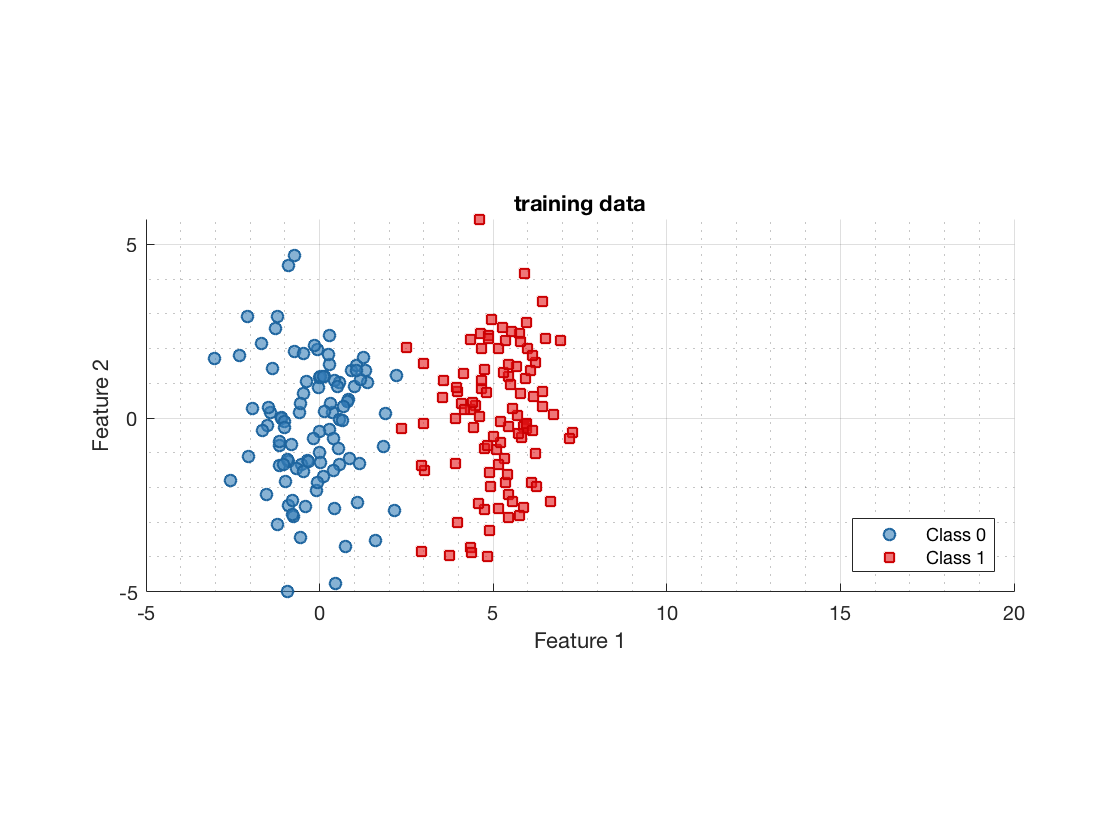

mu0 = [0,0];
mu1 = [5,0];
theta = pi/2;
R = @(t)[cos(t), sin(t);
    -sin(t), cos(t)];
Sigma = R(theta)*diag([4,1])*R(theta).';
N = 100;

ds_train = prtDataGenUnimodal(N,mu0,mu1,Sigma,Sigma);
plot(ds_train)
axis equal tight
xlim([-5,20])
title('training data')

Build testing dataset

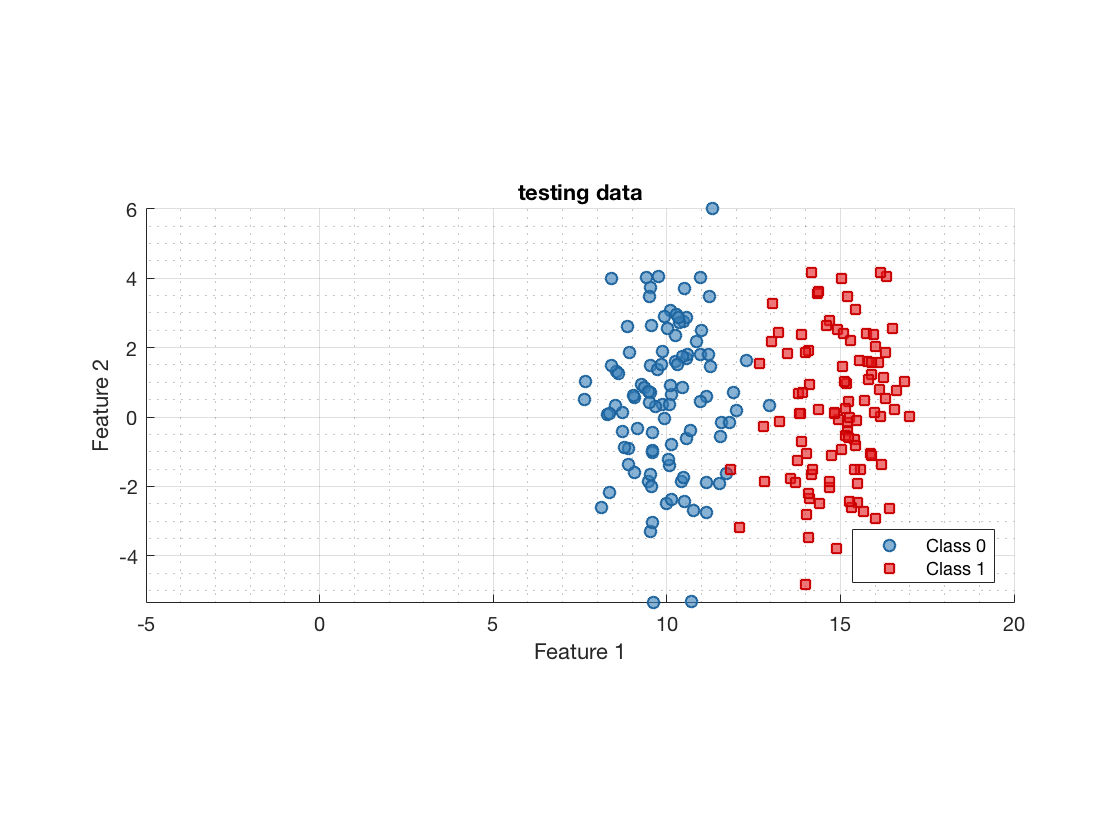

ds_test = prtDataGenUnimodal(N,mu0+[10,0],mu1+[10,0],Sigma,Sigma);
plot(ds_test)
axis equal tight
xlim([-5,20])
title('testing data')

Run "classifier" on training set - outputs decision scores

X = ds_train.X;
Y = ds_train.Y;
w = [1;0];
scores = X*w;
ds_train_scores = prtDataSetClass(scores,Y);

Train decider

decider = prtDecisionBinaryMinPe;
decider_trained = decider.train(ds_train_scores);
threshold = decider_trained.threshold

threshold =    2.369404179689425


Run "classifier" on testing set

X = ds_test.X;
Y = ds_test.Y;
scores = X(:,1);
ds_test_scores = prtDataSetClass(scores,Y);

Run decider on testing set

results = decider_trained.run(ds_test_scores);
prtScoreRoc(results)
results_incestuous = decider.rt(ds_test_scores);
hold on
prtScoreRoc(results_incestuous)
hold off
prtScorePercentCorrect(results)

ans =    0.500000000000000


prtScorePercentCorrect(results_incestuous)

ans =    0.985000000000000


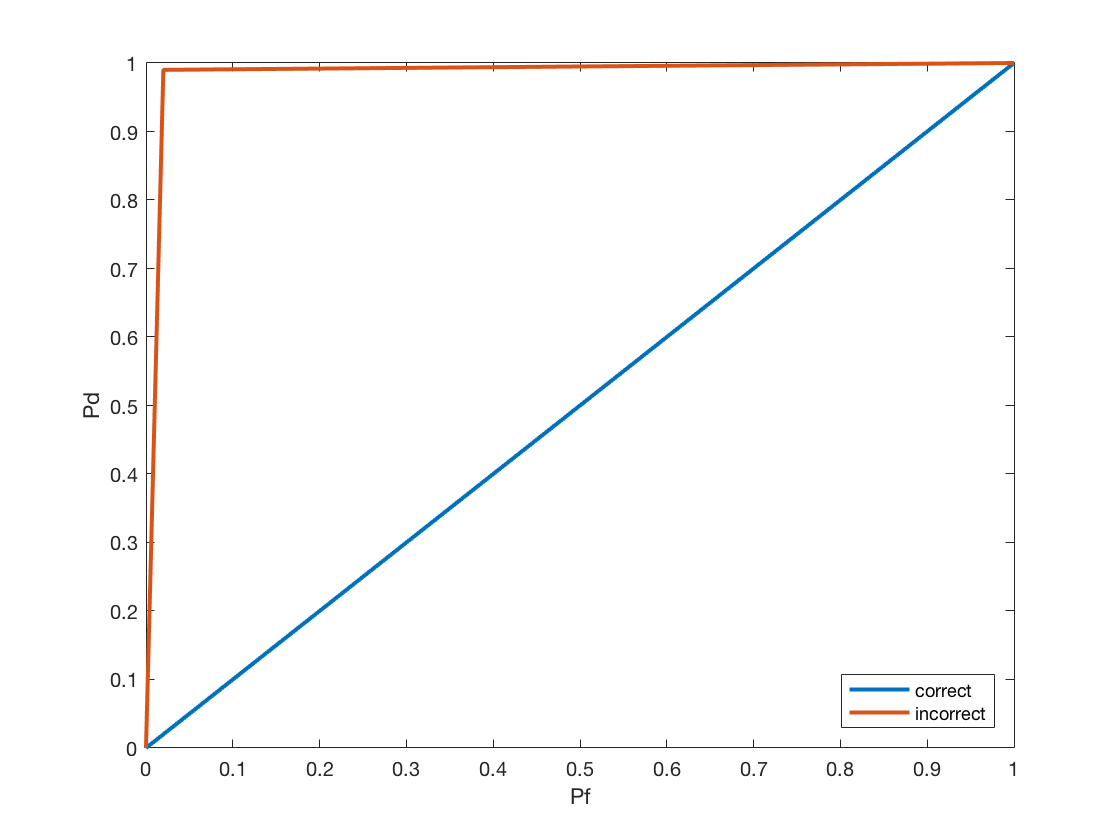

legend('correct','incorrect','Location','southeast')